% Define the local API URL
url = 'http://192.168.1.109:5000/files';
options = weboptions('Timeout', 10);

% Send GET request to retrieve file details
try
    response = webread(url, options);  % Sends GET request to the API

    % Assuming the response is an array of structs
    disp('Files available on the server:');
    for i = 1:length(response)
        fprintf('Filename: %s\n', response(i).filename);
    end

catch exception
    disp('Error retrieving file details from the API:');
    disp(getReport(exception));
end

Files available on the server:


Filename: recorded_sound_0.wav
Filename: recorded_sound_1.wav
Filename: Dtmf-1.wav
Filename: recorded_sound_4.wav
Filename: recorded_sound_3.wav
Filename: recorded_sound_2.wav
Filename: Faulty1_Peak_4.wav
Filename: Faulty1_Peak_5.wav
Filename: Faulty1_Peak_6.wav
Filename: Faulty1_Peak_7.wav
Filename: Faulty1_Peak_8.wav
Filename: Faulty1_Peak_9.wav
Filename: Faulty1_Peak_10.wav
Filename: Faulty1_Peak_11.wav
Filename: Faulty1_Peak_12.wav
Filename: Faulty1_Peak_13.wav
Filename: Faulty1_Peak_14.wav
Filename: Faulty1_Peak_15.wav
Filename: Faulty1_Peak_16.wav
Filename: Faulty1_Peak_17.wav
Filename: Faulty1_Peak_18.wav
Filename: Faulty1_Peak_19.wav
Filename: Faulty1_Peak_20.wav
Filename: Faulty1_Peak_21.wav
Filename: Faulty1_Peak_22.wav
Filename: Faulty1_Peak_23.wav
Filename: Faulty1_Peak_24.wav
Filename: Faulty1_Peak_25.wav
Filename: Faulty1_Peak_26.wav
Filename: Faulty1_Peak_27.wav
Filename: Faulty1_Peak_28.wav
Filename: Faulty1_Peak_29.wav
Filename: Faulty1_Peak_30.wav
Filename: Faulty1_Pe


% Define the download URL
download_url = 'http://192.168.1.109:5000/download/Normal3_peak_21.wav';
output_filename = 'Normal3_peak_21.wav'; % Filename to save locally

% Download the file and save it locally
try
    websave(output_filename, download_url, options);
    disp(['File downloaded and saved as ', output_filename]);
catch exception
    disp('Error downloading the file from the API:');
    disp(getReport(exception));
end

File downloaded and saved as Normal3_peak_21.wav



% Use the downloaded file for further analysis
filename = output_filename;

% Read the audio file
[x, Fs] = audioread(filename);

% Display basic information about the audio file
fprintf('Sample rate: %d Hz\n', Fs);

Sample rate: 48000 Hz


fprintf('Number of samples: %d\n', length(x));

Number of samples: 48001


fprintf('Duration: %.2f seconds\n', length(x) / Fs);

Duration: 1.00 seconds


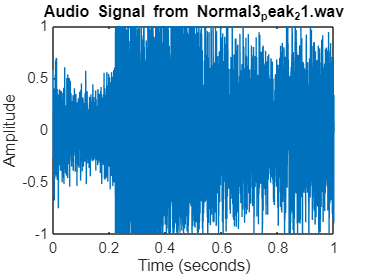


% Plot the audio signal
figure;
plot((1:length(x))/Fs, x);
xlabel('Time (seconds)');
ylabel('Amplitude');
title(['Audio Signal from ', filename]);


% Analysis example: Calculate and display the RMS value of the signal
rmsValue = rms(x);
fprintf('RMS value of the signal: %.4f\n', rmsValue);

RMS value of the signal: 0.4424



% Analysis example: Zero-Crossing Rate (ZCR)
zcr = sum(abs(diff(x > 0))) / length(x);
fprintf('Zero-Crossing Rate (ZCR): %.4f\n', zcr);

Zero-Crossing Rate (ZCR): 0.1601



% Analysis example: Energy of the signal
energy = sum(x .^ 2);
fprintf('Energy of the signal: %.4f\n', energy);

Energy of the signal: 9396.1121


% Define the filename
filename = 'Normal3_peak_21.wav';

% Read the audio file
[x, Fs] = audioread(filename);

% Display basic information about the audio file
fprintf('Sample rate: %d Hz\n', Fs);

Sample rate: 48000 Hz


fprintf('Number of samples: %d\n', length(x));

Number of samples: 48001


fprintf('Duration: %.2f seconds\n', length(x) / Fs);

Duration: 1.00 seconds



% Plot the audio signal
figure;
plot((1:length(x))/Fs, x);
xlabel('Time (seconds)');
ylabel('Amplitude');
title('Audio Signal from Normal3_peak_21.wav');


% Analysis example: Calculate and display the RMS value of the signal
rmsValue = rms(x);
fprintf('RMS value of the signal: %.4f\n', rmsValue);

RMS value of the signal: 0.4424



% Analysis example: Zero-Crossing Rate (ZCR)
zcr = sum(abs(diff(x > 0))) / length(x);
fprintf('Zero-Crossing Rate (ZCR): %.4f\n', zcr);

Zero-Crossing Rate (ZCR): 0.1601



% Analysis example: Energy of the signal
energy = sum(x .^ 2);
fprintf('Energy of the signal: %.4f\n', energy);

Energy of the signal: 9396.1121
